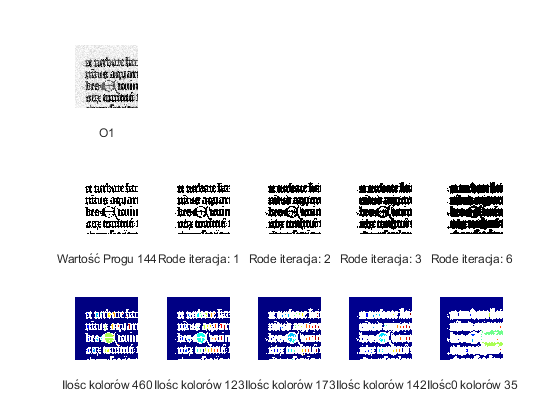

%zad4
clc; close all
O1=rgb2gray(imread("1.png"));
O1op=graythresh(O1)*255;
O1obin=binarka(O1,O1op);
se = strel('diamond',1);
for i=1:8
    if(i==1)
        Ro=imerode(O1obin,se);
        Di=imdilate(O1obin,se);
        Op=imopen(O1obin,se);
        Cl=imclose(O1obin,se);
    else
        Ro=imerode(Ro,se);
        Di=imdilate(Di,se);
        Op=imopen(Op,se);
        Cl=imclose(Cl,se);  
    end
    if(i==1)
    Ro1=Ro;    
    Di1=Di;
    Op1=Op;
    Cl1=Cl;
    end
    if(i==2)
    Ro2=Ro;    
    Di2=Di;
    Op2=Op;
    Cl2=Cl;
    end
    if(i==3)
    Ro3=Ro;    
    Di3=Di;
    Op3=Op;
    Cl3=Cl;
    end
    if(i==6)
    Ro6=Ro;    
    Di6=Di;
    Op6=Op;
    Cl6=Cl;
    end
end

kbin=bwlabel(O1obin);
rk1=max(unique(kbin))+1;
kbin=label2rgb(kbin);

kro1=bwlabel(Ro1);
rk2=max(unique(kro1))+1;
kro1=label2rgb(kro1);

kro2=bwlabel(Ro2);
rk3=max(unique(kro2))+1;
kro2=label2rgb(kro2);

kro3=bwlabel(Ro3);
rk4=max(unique(kro3))+1;
kro3=label2rgb(kro3);

kro6=bwlabel(Ro6);
rk5=max(unique(kro6))+1;
kro6=label2rgb(kro6);

A=figure();
subplot(3,5,1);
imshow(O1);
xlabel("O1")
subplot(3,5,6);
imshow(O1obin);
xlabel("Wartość Progu "+O1op)
subplot(3,5,7);
imshow(Ro1)
xlabel("Rode iteracja: 1")
subplot(3,5,8);
imshow(Ro2)
xlabel("Rode iteracja: 2")
subplot(3,5,9);
imshow(Ro3)
xlabel("Rode iteracja: 3")
subplot(3,5,10);
imshow(Ro6)
xlabel("Rode iteracja: 6")
subplot(3,5,11);
imshow(kbin);
xlabel("Ilośc kolorów " +rk1)
subplot(3,5,12);
imshow(kro1);
xlabel("Ilośc kolorów " +rk2)
subplot(3,5,13);
imshow(kro2);
xlabel("Ilośc kolorów " +rk3)
subplot(3,5,14);
imshow(kro3);
xlabel("Ilośc kolorów " +rk4)
subplot(3,5,15);
imshow(kro6);
xlabel("Ilośc0 kolorów " +rk5)

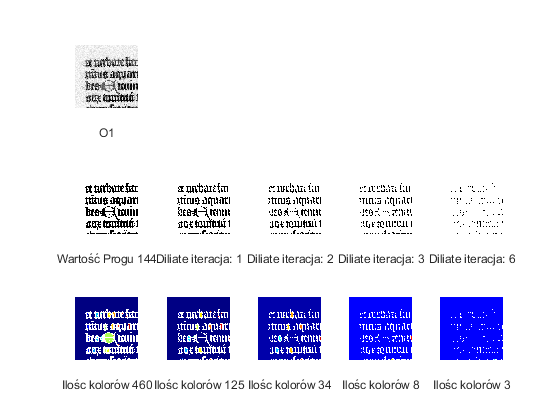




dio1=bwlabel(Di1);
dk2=max(unique(dio1))+1;
dio1=label2rgb(dio1);

dio2=bwlabel(Di2);
dk3=max(unique(dio2))+1;
dio2=label2rgb(dio2);

dio3=bwlabel(Di3);
dk4=max(unique(dio3))+1;
dio3=label2rgb(dio3);

dio6=bwlabel(Di6);
dk5=max(unique(dio6))+1;
dio6=label2rgb(dio6);

B=figure();
subplot(3,5,1);
imshow(O1);
xlabel("O1")
subplot(3,5,6);
imshow(O1obin);
xlabel("Wartość Progu "+O1op)
subplot(3,5,7);
imshow(Di1)
xlabel("Diliate iteracja: 1")
subplot(3,5,8);
imshow(Di2)
xlabel("Diliate iteracja: 2")
subplot(3,5,9);
imshow(Di3)
xlabel("Diliate iteracja: 3")
subplot(3,5,10);
imshow(Di6)
xlabel("Diliate iteracja: 6")
subplot(3,5,11);
imshow(kbin);
xlabel("Ilośc kolorów " +rk1)
subplot(3,5,12);
imshow(dio1);
xlabel("Ilośc kolorów " +dk2)
subplot(3,5,13);
imshow(dio2);
xlabel("Ilośc kolorów " +dk3)
subplot(3,5,14);
imshow(dio3);
xlabel("Ilośc kolorów " +dk4)
subplot(3,5,15);
imshow(dio6);
xlabel("Ilośc kolorów " +dk5)

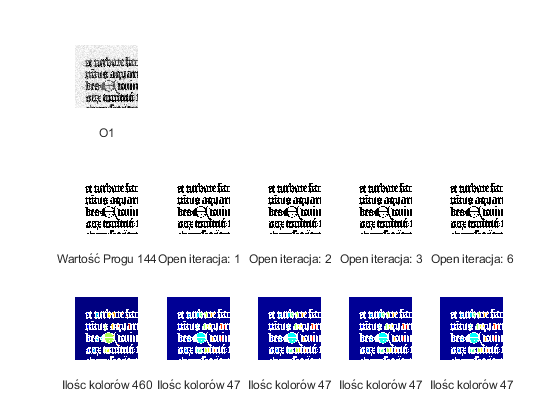



opo1=bwlabel(Op1);
op2=max(unique(opo1))+1;
opo1=label2rgb(opo1);

opo2=bwlabel(Op2);
op3=max(unique(opo2))+1;
opo2=label2rgb(opo2);

opo3=bwlabel(Op3);
op4=max(unique(opo3))+1;
opo3=label2rgb(opo3);

opo6=bwlabel(Op6);
op5=max(unique(opo6))+1;
opo6=label2rgb(opo6);

C=figure();
subplot(3,5,1);
imshow(O1);
xlabel("O1")
subplot(3,5,6);
imshow(O1obin);
xlabel("Wartość Progu "+O1op)
subplot(3,5,7);
imshow(Op1)
xlabel("Open iteracja: 1")
subplot(3,5,8);
imshow(Op2)
xlabel("Open iteracja: 2")
subplot(3,5,9);
imshow(Op3)
xlabel("Open iteracja: 3")
subplot(3,5,10);
imshow(Op6)
xlabel("Open iteracja: 6")
subplot(3,5,11);
imshow(kbin);
xlabel("Ilośc kolorów " +rk1)
subplot(3,5,12);
imshow(opo1);
xlabel("Ilośc kolorów " +op2)
subplot(3,5,13);
imshow(opo2);
xlabel("Ilośc kolorów " +op3)
subplot(3,5,14);
imshow(opo3);
xlabel("Ilośc kolorów " +op4)
subplot(3,5,15);
imshow(opo6);
xlabel("Ilośc kolorów " +op5)

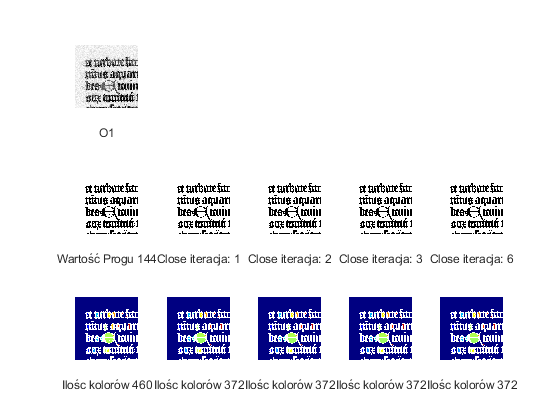


clo1=bwlabel(Cl1);
cp2=max(unique(clo1))+1;
clo1=label2rgb(clo1);

clo2=bwlabel(Cl2);
cp3=max(unique(clo2))+1;
clo2=label2rgb(clo2);

clo3=bwlabel(Cl3);
cp4=max(unique(clo3))+1;
clo3=label2rgb(clo3);

clo6=bwlabel(Cl6);
cp5=max(unique(clo6))+1;
clo6=label2rgb(clo6);

D=figure();
subplot(3,5,1);
imshow(O1);
xlabel("O1")
subplot(3,5,6);
imshow(O1obin);
xlabel("Wartość Progu "+O1op)
subplot(3,5,7);
imshow(Cl1)
xlabel("Close iteracja: 1")
subplot(3,5,8);
imshow(Cl2)
xlabel("Close iteracja: 2")
subplot(3,5,9);
imshow(Cl3)
xlabel("Close iteracja: 3")
subplot(3,5,10);
imshow(Cl6)
xlabel("Close iteracja: 6")
subplot(3,5,11);
imshow(kbin);
xlabel("Ilośc kolorów " +rk1)
subplot(3,5,12);
imshow(clo1);
xlabel("Ilośc kolorów " +cp2)
subplot(3,5,13);
imshow(clo2);
xlabel("Ilośc kolorów " +cp3)
subplot(3,5,14);
imshow(clo3);
xlabel("Ilośc kolorów " +cp4)
subplot(3,5,15);
imshow(clo6);
xlabel("Ilośc kolorów " +cp5)